clf;
clear;

Goldhill = imread("../materials/Goldhill_noised.tif");
size(Goldhill)

ans =    512   512


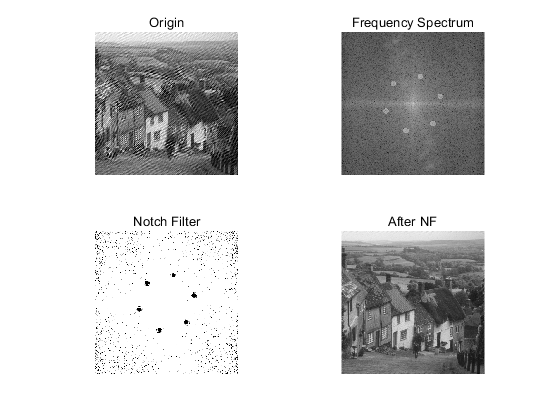


FFT_Goldhill = fftshift(fft2(im2double(im2gray(Goldhill))));
[NF_Filter,NF_Goldhill] = my_notch(Goldhill,4);

figure;
subplot(2,2,1);
imshow(Goldhill);title('Origin');
subplot(2,2,2);
imshow(log(abs(FFT_Goldhill)),[]);title('Frequency Spectrum');
subplot(2,2,3);
imshow(log(abs(NF_Filter)));title('Notch Filter');
subplot(2,2,4);
imshow(NF_Goldhill);title('After NF');

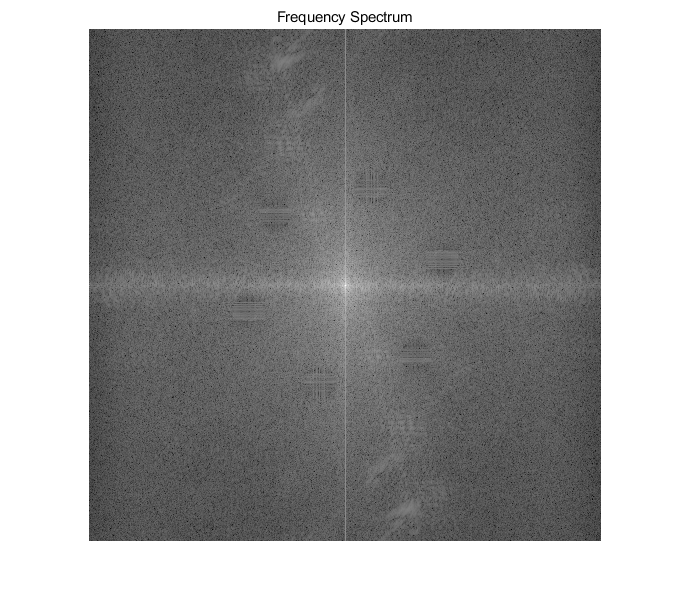


figure;
FFT_NF = fftshift(fft2(im2double(im2gray(NF_Goldhill))));
imshow(log(abs(FFT_NF)),[]);title('Frequency Spectrum');

function [NF_Filter,NF_Goldhill] = my_notch(image,set)
    [M,N] = size(image);
    D0=30;
    m=M*2;
    n=N*2;
    H=ones(m,n);

    u0 = 140; v0 = 140;
    for x = (-m/2):(m/2)-1
        for y = (-n/2):(n/2)-1
          Dk = sqrt((x+u0)^2+(y+v0)^2);
          H(x+(m/2)+1,y+(n/2)+1) = H(x+(m/2)+1,y+(n/2)+1) * 1/(1+(D0/Dk)^(2*set));
          Dk = sqrt((x-u0)^2+(y-v0)^2);
          H(x+(m/2)+1,y+(n/2)+1) = H(x+(m/2)+1,y+(n/2)+1) * 1/(1+(D0/Dk)^(2*set));
        end
    end

    u0 = -50; v0 = 195;
    for x = (-m/2):(m/2)-1
        for y = (-n/2):(n/2)-1
          Dk = sqrt((x+u0)^2+(y+v0)^2);
          H(x+(m/2)+1,y+(n/2)+1) = H(x+(m/2)+1,y+(n/2)+1) * 1/(1+(D0/Dk)^(2*set));
          Dk = sqrt((x-u0)^2+(y-v0)^2);
          H(x+(m/2)+1,y+(n/2)+1) = H(x+(m/2)+1,y+(n/2)+1) * 1/(1+(D0/Dk)^(2*set));
        end
    end

    u0 = -195; v0 = 50;
    for x = (-m/2):(m/2)-1
        for y = (-n/2):(n/2)-1
          Dk = sqrt((x+u0)^2+(y+v0)^2);
          H(x+(m/2)+1,y+(n/2)+1) = H(x+(m/2)+1,y+(n/2)+1) * 1/(1+(D0/Dk)^(2*set));
          Dk = sqrt((x-u0)^2+(y-v0)^2);
          H(x+(m/2)+1,y+(n/2)+1) = H(x+(m/2)+1,y+(n/2)+1) * 1/(1+(D0/Dk)^(2*set));
        end
    end
    NF_Filter = H .* fftshift(fft2(im2double(im2gray(image)),m,n));
    NF_Goldhill = real(ifft2(ifftshift(NF_Filter)));
    NF_Goldhill = NF_Goldhill(1:M,1:N);
end